Preparing data set from video

- In Matlab,  Apps -> Video Labeller -> Import -> Select the video need to be labeled -> Label -> Give Label Name and description -> Select shape to label      ->Go for labeling

- Save the file as .mat

load gTruth.mat
gTruth

gTruth =   groundTruth with properties:

          DataSource: [1×1 groundTruthDataSource]
    LabelDefinitions: [1×5 table]
           LabelData: [159×1 timetable]


[imgs,lab] = objectDetectorTrainingData(gTruth,...
    SamplingFactor=1,WriteLocation = "training\");

Write images extracted for training to folder: 
    training\

Writing 143 images extracted from v_Bowling_g01_c01.avi...Completed.


Training a detctor

imgsWithLabels = combine(imgs,lab) %Combining image with label for training

imgsWithLabels =   CombinedDatastore with properties:

      UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}
    SupportedOutputFormats: ["txt"    "csv"    "dat"    "asc"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "wav"    "flac"    "ogg"    "opus"    "mp3"    "mp4"    "m4a"]


detector = trainACFObjectDetector(imgsWithLabels,...
    NumStages = 20)

ACF Object Detector Training
The training will take 20 stages. The model size is 12x11.
Sample positive examples(~100% Completed)
Compute approximation coefficients...Completed.
Compute aggregated channel features...Completed.
--------------------------------------------
Stage 1:
Sample negative examples(~100% Completed)
Compute aggregated channel features...Completed.
Train classifier with 147 positive examples and 735 negative examples...Completed.
The trained classifier has 79 weak learners.
--------------------------------------------
Stage 2:
Sample negative examples(~100% Completed)
Found 735 new negative examples for training.
Compute aggregated channel features...Completed.
Train classifier with 147 positive examples and 735 negative examples...Completed.
The trained classifier has 256 weak learners.
--------------------------------------------
Stage 3:
Sample negative examples(~100% Completed)
Found 735 new negative examples for training.
Compute aggregated channel features...

detector =   acfObjectDetector with properties:

             ModelName: 'Ball'
    ObjectTrainingSize: [12 11]
       NumWeakLearners: 746


Inference

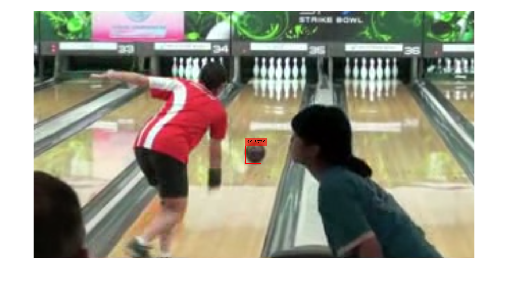

tImg = imread("InferenceImage.png");
[bb, s] = detect(detector, tImg);
infImg = insertObjectAnnotation(tImg,"rectangle",bb, s, AnnotationColor="red");
imshow(infImg)

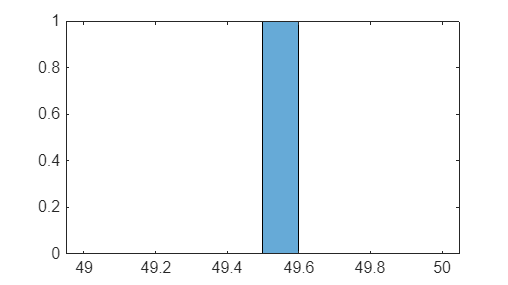

histogram(s, 10)